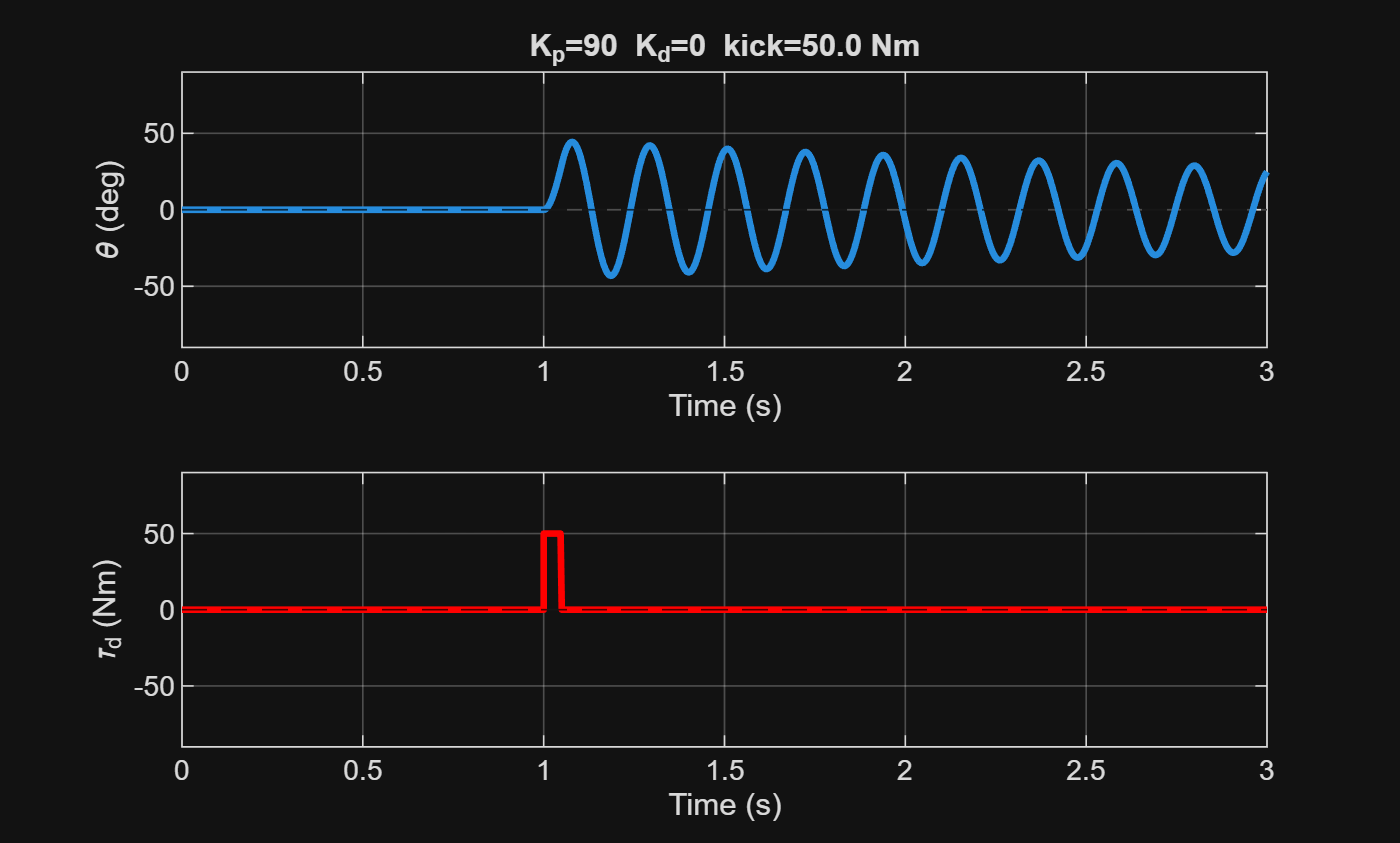

clc;
clear all;

%% Inverted pendulum: disturbance rejection (L1 demo)
% Tune these with sliders in Live Editor:
Kp =90;    % proportional gain   (slider 0 to 200)
Kd =0;    % derivative gain   (slider 0 to 50)
tau_d =50;   % kick magnitude (Nm) (slider 0 to 100)
 % 50 ms impulse at t=1
t_d_start = 1;
t_d_end = 1.05;
 

% Fixed plant parameters
J = 0.10; b = 0.05; m = 1.0; g = 9.81; L = 0.5;

function dy = pend(t, y, Kp, Kd, tau_d, J, b, m, g, L, t_d_start, t_d_end)
theta = y(1); theta_dot = y(2);
kick  = tau_d * (t > t_d_start && t < t_d_end);          
tau   = -Kp*theta - Kd*theta_dot;             % PD control
ddot  = ( m*g*L*sin(theta) - b*theta_dot + tau + kick ) / J;
dy    = [theta_dot; ddot];
end

% Simulate
opts = odeset('MaxStep', 0.005);   % cap at 5 ms
[t, y] = ode45(@(t,y) pend(t,y,Kp,Kd,tau_d,J,b,m,g,L, t_d_start, t_d_end), [0 3], [0;0], opts);
tau_t = tau_d * (t > t_d_start & t < t_d_end);

% Plot
figure;
subplot(2,1,1)
plot(t, y(:,1)*180/pi, 'LineWidth', 2);
yline(0, 'k--'); xlabel('Time (s)'); ylabel('\theta (deg)');
title(sprintf('K_p=%.0f  K_d=%.0f  kick=%.1f Nm', Kp, Kd, tau_d));
ylim([-90 90]); grid on;

% Plot
% figure;
subplot(2,1,2)
plot(t, tau_t, 'LineWidth', 2, 'Color','r');
yline(0, 'k--'); xlabel('Time (s)'); ylabel('\tau_d (Nm)');
% title(sprintf('K_p=%.0f  K_d=%.0f  kick=%.1f Nm', Kp, Kd, tau_d));
ylim([-90 90]); grid on;

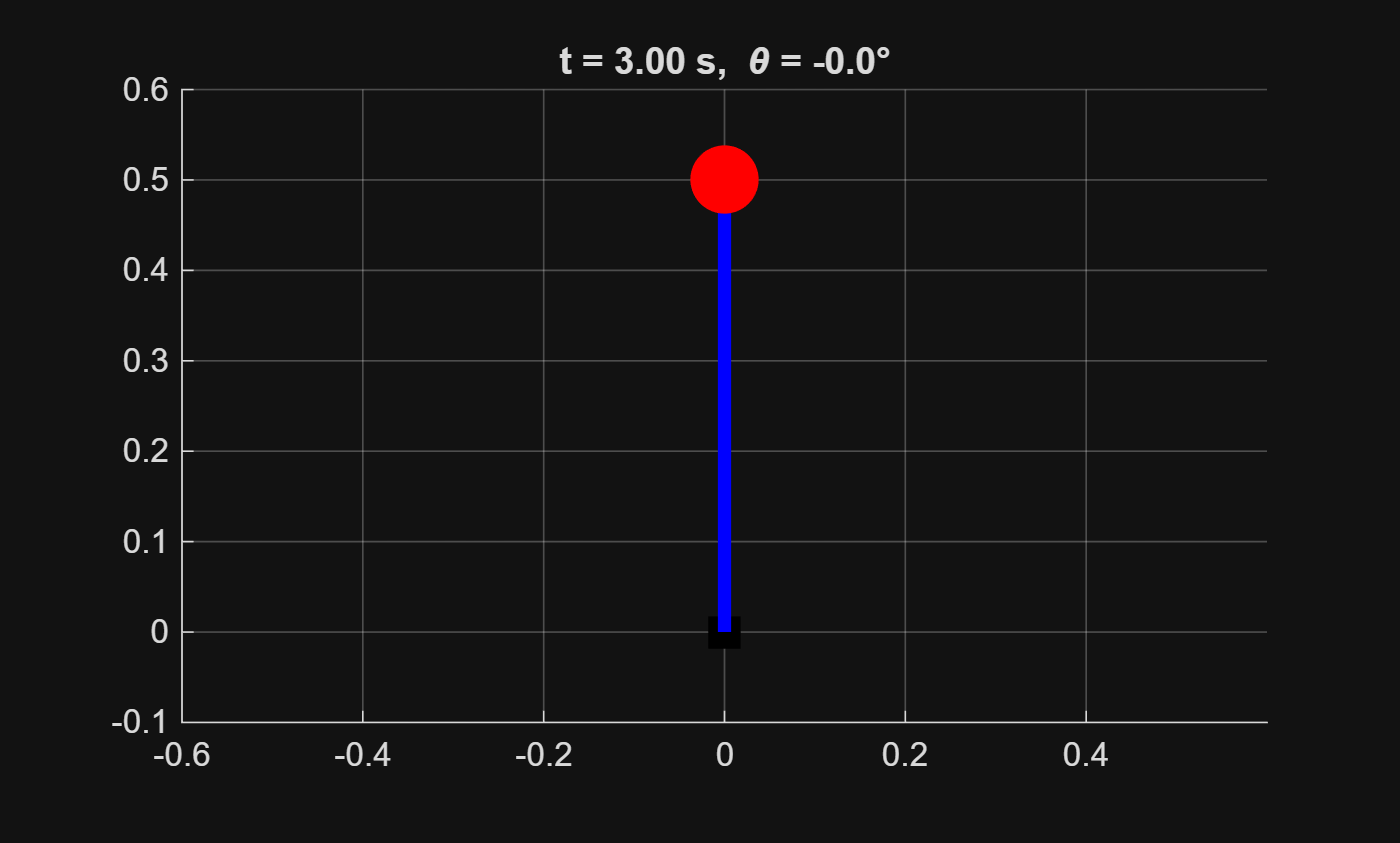


%% Animate (press button to play)
 

L_arm = L;                            % visual rod length (use your plant's L)
fps   = 30;                           % playback frame rate (Hz)

% Figure + axes (created once per button press)
figure(2); clf;
axis equal; axis([-1.2*L_arm 1.2*L_arm -0.2*L_arm 1.2*L_arm]);
grid on; hold on;
plot(0, 0, 'ks', 'MarkerSize', 12, 'MarkerFaceColor', 'k');   % pivot

% Dynamic objects — keep handles so we can update them
rod    = plot([0 0], [0 L_arm], 'b-', 'LineWidth', 4);
bob    = plot(0, L_arm, 'ro', 'MarkerSize', 20, 'MarkerFaceColor', 'r');
ttl    = title('t = 0.00 s,  \theta = 0.0°');

% Decimate solver output to ~fps frames over the full sim time
n_frames  = max(2, round(fps * t(end)));
frame_idx = round(linspace(1, length(t), n_frames));

% Play
for k = frame_idx
    theta = y(k, 1);
    x = L_arm * sin(theta);   yc = L_arm * cos(theta);
    set(rod, 'XData', [0 x], 'YData', [0 yc]);
    set(bob, 'XData', x,     'YData', yc);
    set(ttl, 'String', sprintf('t = %.2f s,  \\theta = %.1f°', ...
        t(k), theta*180/pi));
    drawnow limitrate;
    pause(1/fps);
end